close all;clear all; clc;

Lya_index = 2;
sys = p4_system_formulate; 
sys.f = p4_gp(sys);

Function evaluation      0;  Value -9.818831e+02
Function evaluation      8;  Value -1.053531e+03
Function evaluation     10;  Value -1.076504e+03
Function evaluation     13;  Value -1.077486e+03
Function evaluation     15;  Value -1.079242e+03
Function evaluation     19;  Value -1.079674e+03
Function evaluation     20;  Value -1.080159e+03
Function evaluation     22;  Value -1.080276e+03
Function evaluation     24;  Value -1.080492e+03
Function evaluation     25;  Value -1.080729e+03
Function evaluation     28;  Value -1.081629e+03
Function evaluation     33;  Value -1.081963e+03
Function evaluation     35;  Value -1.082476e+03
Function evaluation     39;  Value -1.082533e+03
Function evaluation     41;  Value -1.082626e+03
Function evaluation     43;  Value -1.082785e+03
Function evaluation     45;  Value -1.083151e+03
Function evaluation     47;  Value -1.083271e+03
Function evaluation     49;  Value -1.083303e+03
Function evaluation     52;  Value -1.083472e+03
Function evaluation 

sys.plott = 1; % Plot figure

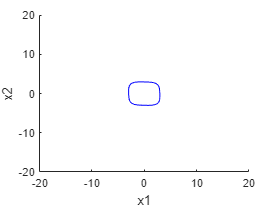

sys = p4_s1_lya_sublevelset(sys,Lya_index);

Elapsed time is 109.695698 seconds.


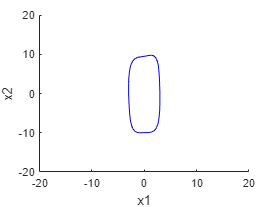

[opt_input, sys] = p4_s2_opt_barrier(sys);

bar_flag = sys.exist_bar

bar_flag =      1


%% Check permissive Lyapunov function
if isequal(bar_flag,1)
    %         sys.exist_bar = 1;
    [coe, fac] = coeffs(p2s(opt_input));
    coe = double(coe);
    fac = char(fac);
    save('.\mat\gp_coe.mat','coe')
else
    %         sys.exist_bar = 0;
    opt_input = sys.cv-sys.V(Lya_index);
    [coe, fac] = coeffs(p2s(opt_input));
    coe = double(coe);
    fac = char(fac);
    save('.\mat\gp_coe.mat','coe')
end